# Actividad 3 (Evaluación)

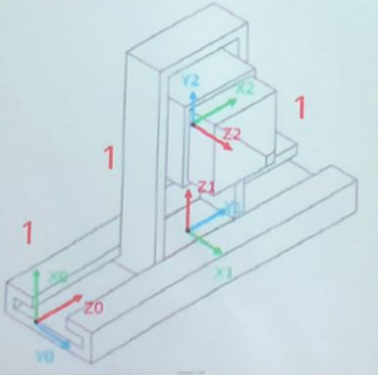

%limpieza de pantalla
clear all
close all
clc

Para este primer robot los grados de libertad que se manejan son 3 y el tipo de articulaciones que tiene son prismaticas por lo cuan en su configuracion lo definimos con 1. Ya que no existen movimientos angulares no se requiere de variables th, ni identitades trigonometricas.

%declaracion de variables simbolicas
syms l1(t) l2(t) l3(t) t 

%confuguracion del robot, 0 para junta rotacional, 1para junta prismatica/lineal
RP=[1 1 1];

%creamos el vector de coordenadas articulares
Q= [l1, l2, l3];

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);


Para cada sistema debemos asegurarnos de que el eje z este colocado conforme a la direccion de su movimento, en la primera articulacion se rota el eje x -90 grados tomando en cuenta el marco de referencia inercial, despues en la segunda articulacion se rota el eje y para que el marco de referencia y la direccion del movimiento coincidan, en la tercer articulacion el eje z ya se encuentra en su ubicacion necesaria

%Articulación 1 
%traslacion en z1 _
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1)= [0  0  -1;
           0  1  0;
           1  0  0];
%Articulación 2 
%Posición de la articulación 2 respecto a 0
P(:,:,2)= [0 ; 0; l2];
%Matriz de rotación de la junta 1 respecto a 0.... -90º a rededor de y1 
R(:,:,2)= [1  0  0 ;
           0  0  1;
           0  -1  0];

%Articulación 3 
%Posición de la articulación 3 respecto a 0
P(:,:,3)= [0 ; 0; l3];
%Matriz de rotación de la junta 3 respecto a 0.... -90º y1 
R(:,:,3)= [1  0  0 ;
           0  1  0;
           0  0  1];

%creamos un vector de ceros
vector_zeros= zeros(1,3);
%inicializamos las matrices de transformacion homogenea local
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); vector_zeros 1]);
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); vector_zeros 1]);

%inicializamos los vectores de posicion vistos desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL);

%inicializamos las matrices de rotacion vistos desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL);

for i = 1:GDL
    i_str= num2str(i);
    %locales
    %disp(strcat('Matriz de transformacion local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); vector_zeros 1]);
    %pretty (A(:,:,i));

    %globales
    try
        T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i)= A(:,:,i);% CASO ESPECIFICO cuando i=1 nos marcaria erroren try
    end
    disp(strcat('Mariz de trasformacion global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i));

    %matriz de rotacion RO y el vector de translacion PO
    %de la matriz de transformacion homogenea global T(:,:,GDL)
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Mariz de trasformacion global T1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Mariz de trasformacion global T2


/ 0, 1, 0, -l2(t) \
|                 |
| 0, 0, 1,    0   |
|                 |
| 1, 0, 0,  l1(t) |
|                 |
\ 0, 0, 0,    1   /



Mariz de trasformacion global T3


/ 0, 1, 0, -l2(t) \
|                 |
| 0, 0, 1,  l3(t) |
|                 |
| 1, 0, 0,  l1(t) |
|                 |
\ 0, 0, 0,    1   /



A continuacion con el jacobiano obtenemos las velocidades lineales y angulares y lo que deberiamos esperar como resultado en las angulares es cero ya que no existe tal mobimiento en el robot, en cambion en las lineales si ya que contamos con tres articulaciones que generan movimiento y por lo tanto velocidad.

%calculamos el jacobiano lineal y angular de forma analitica
%inicializacion jacobianos analiticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if ((RP(k)==0))%|(RP(k)==1))%casos: articulacion rotacional y prismatica

        %para las articulaciones rotacionales
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%matriz de rotacion de 0 con respecto a 0 es la matriz identidad...
            Jw_a(:,k)= [0,0,1];% si no hay matriz de rotacion previa se obtiene la matriz identidad...
        end
      else
        %para las articulaciones prismaticas
       try
           Jv_a(:,k)= RO(:,3,k-1);
       catch
           Jv_a(:,k)= [0,0,1];%si no hay matriz de rotacion previa se obtiene la matriz ...
       end
           Jw_a(:,k)= [0,0,0];
    end
end
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);

disp('Velocidad lineal obtenido mediante el jacobiano lineal');

Velocidad lineal obtenido mediante el jacobiano lineal


V=simplify (Jv_a*Qp');
pretty (V);

/   ________ \
|    d       |
| - -- l2(t) |
|   dt       |
|            |
|  ________  |
|   d        |
|  -- l3(t)  |
|  dt        |
|            |
|  ________  |
|   d        |
|  -- l1(t)  |
\  dt        /



disp('Velocidad angular obtenido mediante el jacobiano angular');

Velocidad angular obtenido mediante el jacobiano angular


W=simplify (Jw_a*Qp');
pretty (W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /

